**Load Frames**

clear all;
fr1=imread("000831.jpg")

fr1 = 694×1280×3 uint8 array
fr1(:,:,1) =

     0     0     0     0     2    10    14    13    11     9     9    12    16    14     7     1     4     7     9     8     5     3     3     5     0     0     0     0     0     0     2    11     9     9     8     7     6     4     3     3     1     1     1     1     0     0     0     0     1     1     1     1     1     1     1     1     0     0     2     4     6     6     6     5     7     7     5     6     6     7     6     7     2     3     2     4     4     4     4     2     3     2     4     4     4     3     4     4    10     7     3     4     6     7     5     2     1     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     3     2     1     1     1     3     3     7    17    31    27    18    24    26    10    10     4     5    12    16    14    10     9    19    10    13    18    16    20    23   

fr2=imread("000833.jpg")

fr2 = 694×1280×3 uint8 array
fr2(:,:,1) =

     1     0     0     0     0     0     0     4     9    11    12    10     7     6     8    11    21     9     1     4     9    10     7     7     2     2     1     0     0     0     0     0     3    11    19    23    18    11     9    11     8     8     7     6     5     5     5     5     5     5     5     5     5     5     5     5     6     5     3     3     4     6     9    12    12    12    10     9     8    10    10    11    10     9     6     7    14    21    17     7    11     9     7     5     4     3     2     2     7    11    13    11    15    21    21    15    12    10     6     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     9     5     5    10    21    27    28    26    28    12     7    11     9    13    17    13    15    14    12    11    15    22    27   

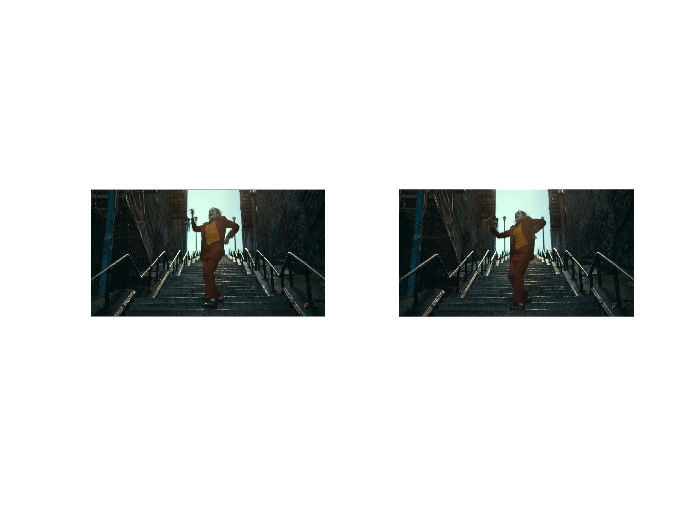


figure();
subplot 121
imshow(fr1);
im1t = im2double(rgb2gray(fr1));
im1 = imresize(im1t, 0.5); % downsize to half

subplot 122
imshow(fr2);

im2t = im2double(rgb2gray(fr2));
im2 = imresize(im2t, 0.5); % downsize to half

## Implementing Lucas Kanade Method

ww = 45;
w = round(ww/2);

% Lucas Kanade Here
% for each point, calculate I_x, I_y, I_t
Ix_m = conv2(im1,[-1 1; -1 1], 'valid'); % partial on x
Iy_m = conv2(im1, [-1 -1; 1 1], 'valid'); % partial on y
It_m = conv2(im1, ones(2), 'valid') + conv2(im2, -ones(2), 'valid'); % partial on t
u = zeros(size(im1));
v = zeros(size(im2));

% within window ww * ww
for i = w+1:size(Ix_m,1)-w
   for j = w+1:size(Ix_m,2)-w
      Ix = Ix_m(i-w:i+w, j-w:j+w);
      Iy = Iy_m(i-w:i+w, j-w:j+w);
      It = It_m(i-w:i+w, j-w:j+w);

      Ix = Ix(:);
      Iy = Iy(:);
      b = -It(:); % get b here

      A = [Ix Iy]; % get A here
      nu = pinv(A)*b; % get velocity here

      u(i,j)=nu(1);
      v(i,j)=nu(2);
   end;
end;

% downsize u and v
u_deci = u(1:10:end, 1:10:end);
v_deci = v(1:10:end, 1:10:end);
% get coordinate for u and v in the original frame
[m, n] = size(im1t);
[X,Y] = meshgrid(1:n, 1:m);
X_deci = X(1:20:end, 1:20:end);
Y_deci = Y(1:20:end, 1:20:end);

## Plot optical flow field

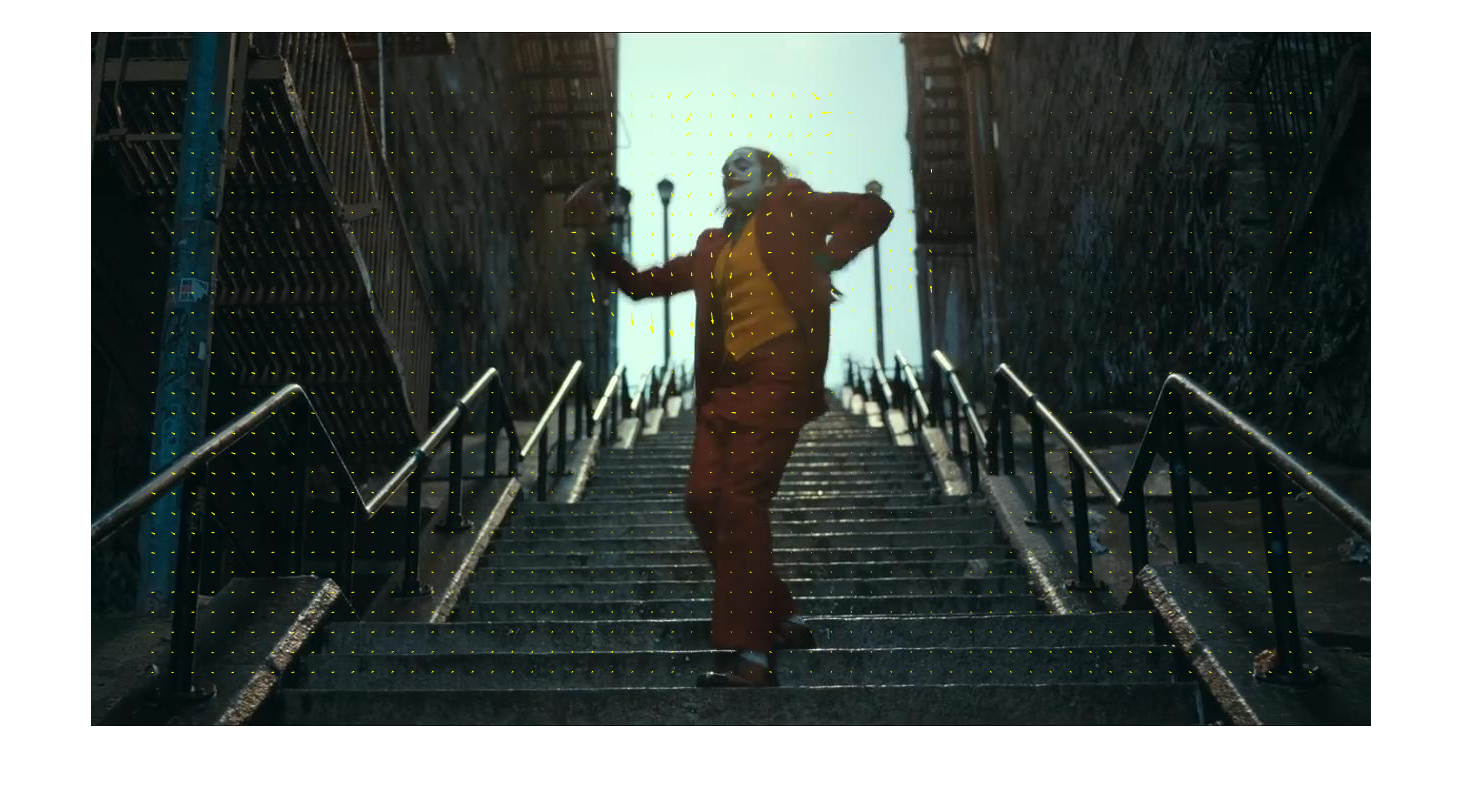

figure();
imshow(fr2);
hold on;
% draw the velocity vectors
quiver(X_deci, Y_deci, u_deci,v_deci, 'y')

imsave